# MXB226 Case Study Modelling an Electronic Component

## Full Storage

load full_storage;
%Solving using cholesky factorisation, then forward and backward
%substitution
A = cholesky(A);
temperatures = forward_substitution(A', b);
temperatures = backward_substitution(A, temperatures);

Visualisating the Temperature from Full Storage

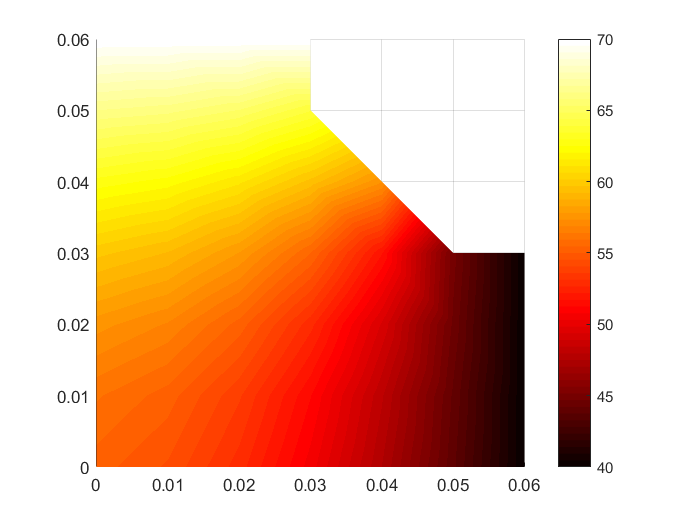

visualisation(temperatures)

## Packed Storage

load full_storage
%NOT CORRECT, NEED TO FIX FORWARD AND BACK SUBS
a = packed_storage(A);
a = Cholesky_Packed(a);
temperatures = packed_forward_substitution(a, b);
temperatures = packed_backward_substitution(a, temperatures);

Visualisating the Temperature from Packed Storage

visualisation(temperatures)

## Band Storage

%RCM Storage
load full_storage
%Create a new matrix to work with
A_RCM = A;
%create ordering vector
p= symrcm(A_RCM);
%order the A matrix and b vector according the RCM storage
A_RCM = A_RCM(p,p);
b_rcm = b(p);
reorder = reorder_vector(p);
%Create a band storage for A
A_band = band(A_RCM);
%Perform cholesky factorisation on the banded matrix
G_Band_then_chol = cholesky_band(A_band, 8);

%solve with forward substitution and then backwards substitution

temperatures = banded_forward_substitution(G_Band_then_chol, b_rcm);
temperatures = banded_backward_substitution(G_Band_then_chol, temperatures);
temperatures = temperatures(reorder);
%Visualisating the Temperature from Band Storage

Visualise the temperatures

visualisation(temperatures)

## Sparse Storage

temperatures = sparseStorage(A, b);

Visualisating the Temperature from Sparse Storage

visualisation(temperatures)

## CSR Storage

clear rb;
[r,c,v] = find(A);
[r_sorted,order] = sort(r);
c = c(order);
v = v(order);

r_current = r_sorted(1);
count = 0;
rb = 1;

for i = 1:length(r_sorted)
    count = count + 1;
    if (r_sorted(i) ~= r_current)
        rb = [rb, count];
        r_current = r_sorted(i);
    end
end

% rb ends with nz + 1, where nz is the total number of nonzero elements in A.
rb = [rb, count + 1];

n = size(A, 1);
x0 = ones(n, 1)*10;
tol = 1e-5;
maxiters = 1000;

Solve CSR Using Jacobi Method

[temperatures, converged, k, res] = jacobi_CSR(rb, c', v', b, x0, tol, maxiters);
converged

converged = logical
   1


k

k = 311

res

res =     0.8301    0.4419    0.3083    0.2518    0.2118    0.1907    0.1711    0.1593    0.1473    0.1393    0.1310    0.1249    0.1187    0.1139    0.1090    0.1049    0.1009    0.0974    0.0939    0.0907    0.0877    0.0848    0.0820    0.0794    0.0769    0.0744    0.0721    0.0698    0.0676    0.0655    0.0635    0.0615    0.0596    0.0577    0.0560    0.0542    0.0526    0.0509    0.0494    0.0478    0.0464    0.0449    0.0436    0.0422    0.0409    0.0396    0.0384    0.0372    0.0361    0.0350


Visualisating the Temperature from Jacobi CSR Storage

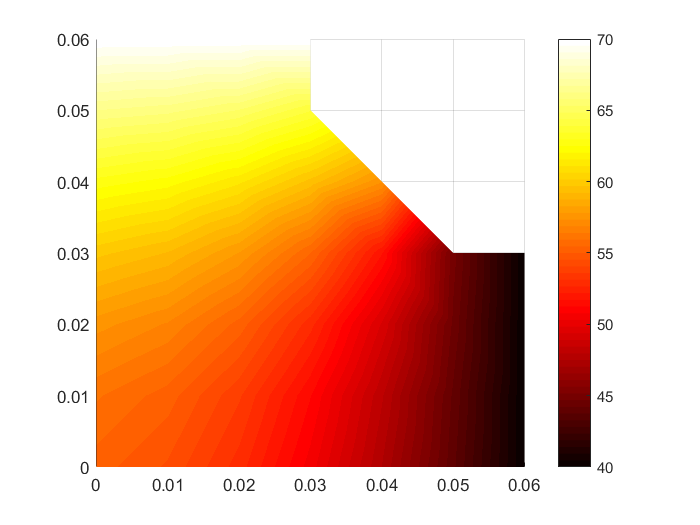

visualisation(temperatures)

Solve CSR Using Gauss Seidel Method

[temperatures, converged, k, res] = gauss_seidel_CSR(rb, c', v', b, x0, tol, maxiters);
converged

converged = logical
   1


k

k = 158

Visualisating the Temperature from Gauss Seidel CSR Storage

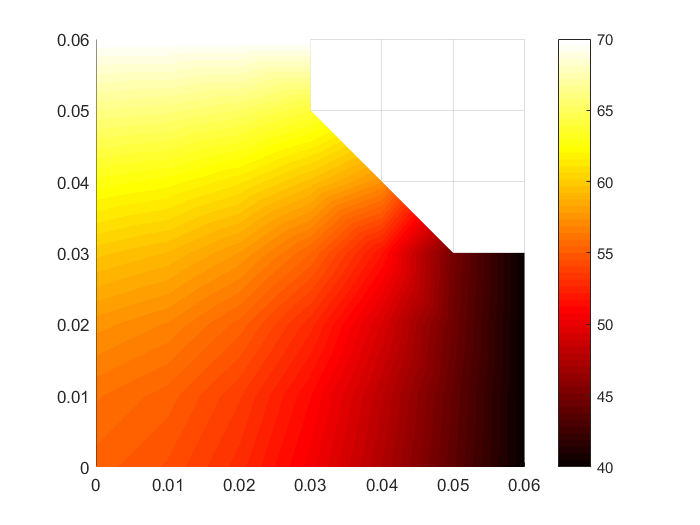

visualisation(temperatures)

Solve CSR Using Conjugate Gradient Method

[temperatures, converged, k, res] = conjugate_gradient_CSR(rb, c', v', b, x0, tol, maxiters);
converged

converged = logical
   1


k

k = 22

Visualisating the Temperature from Conjugate Gradient CSR Storage

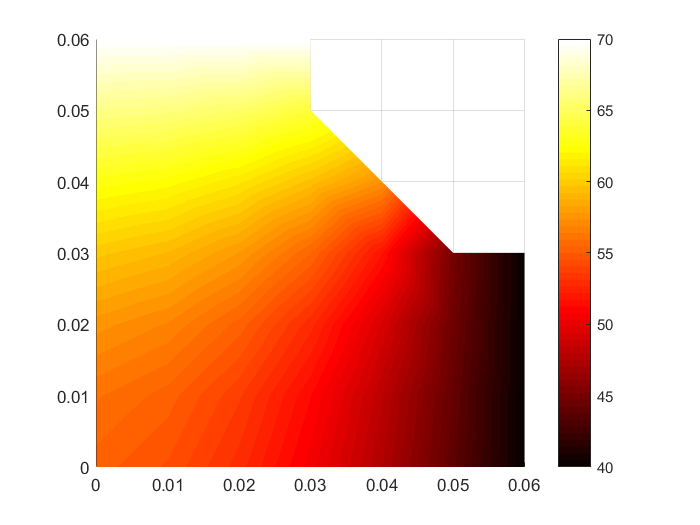

visualisation(temperatures)

Solve CSR Using SOR Method

D = diag(diag(A));
L = tril(A, -1);
U = triu(A, 1);
T_J = - (D \ (L + U));
rhoT_J = max(abs(eig(T_J)));
w_opt = (2 /(1 + sqrt(1 - rhoT_J^2)));

[temperatures, converged, k, res] = sor_CSR(rb, c', v', b, x0, w_opt, tol, maxiters);

Visualisating the Temperature from SOR CSR Storage

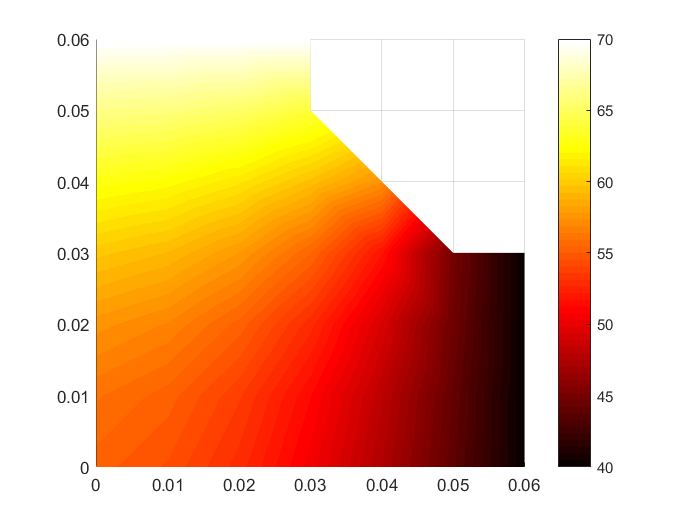

visualisation(temperatures)

## Efficiency Comparison

Bandwidth and level of fill-in for each different Node Ordering

%ffgdfh

Memory (for direct Methods), Iterations (for Iterative Methods), Runtime (Direct and Iterative), Floating Point Operations (direct and iterative).

%ffgdfh

Tolerance that is required for the iterative method to produce a solution that is visually indistinguishable from that produced by the direct methods.

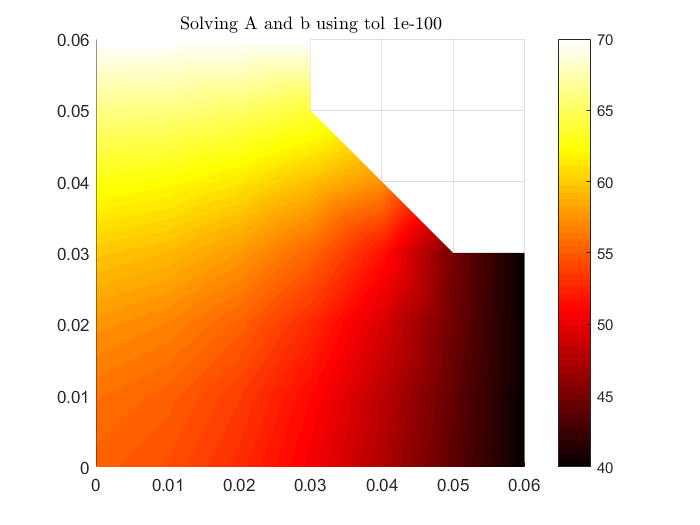

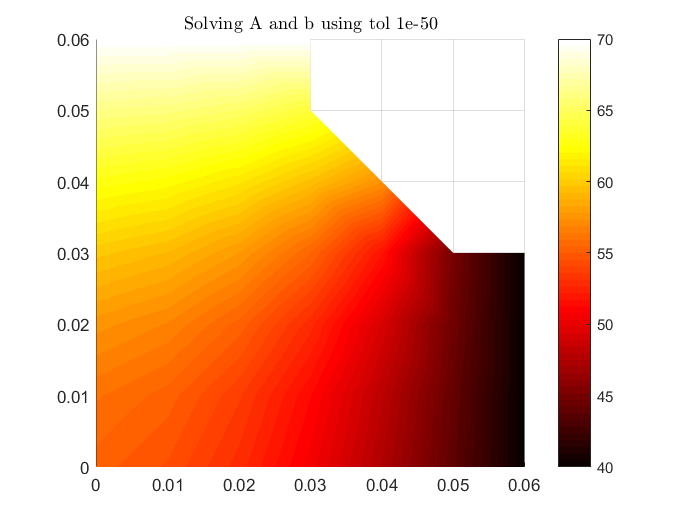

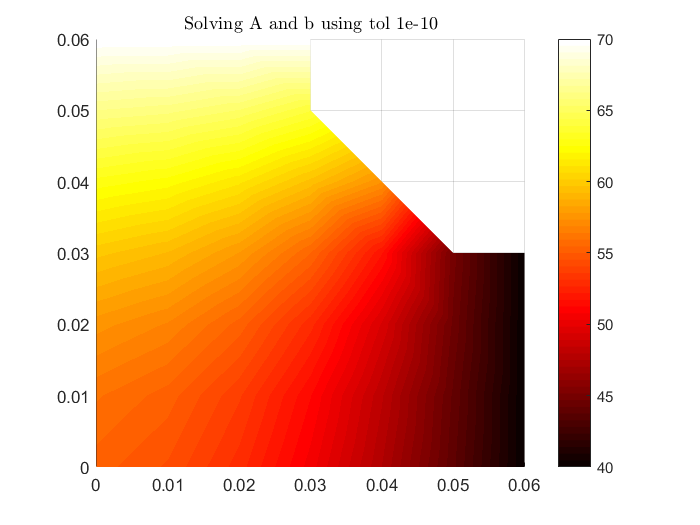

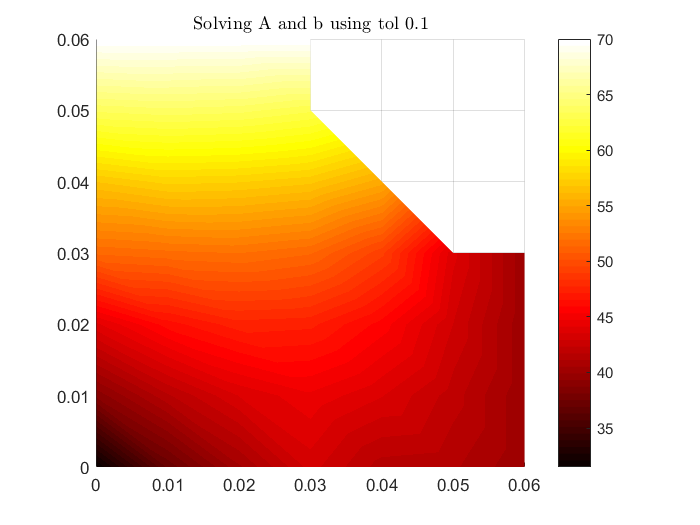

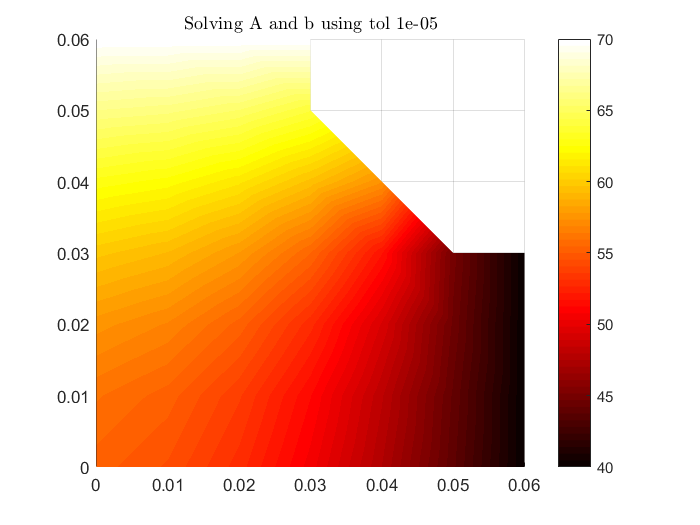

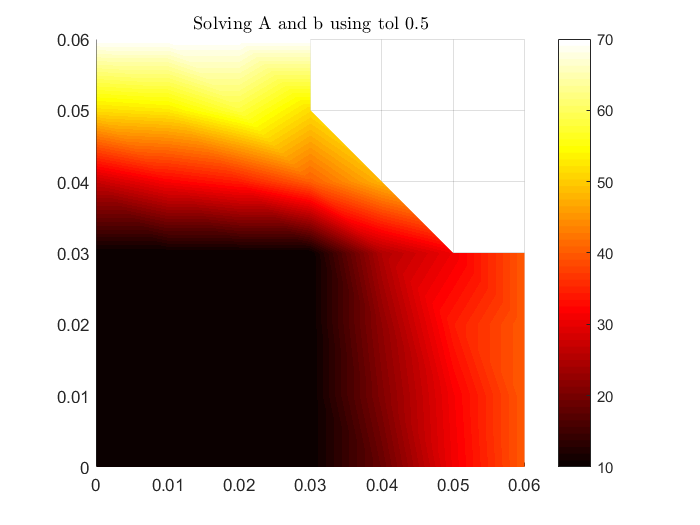

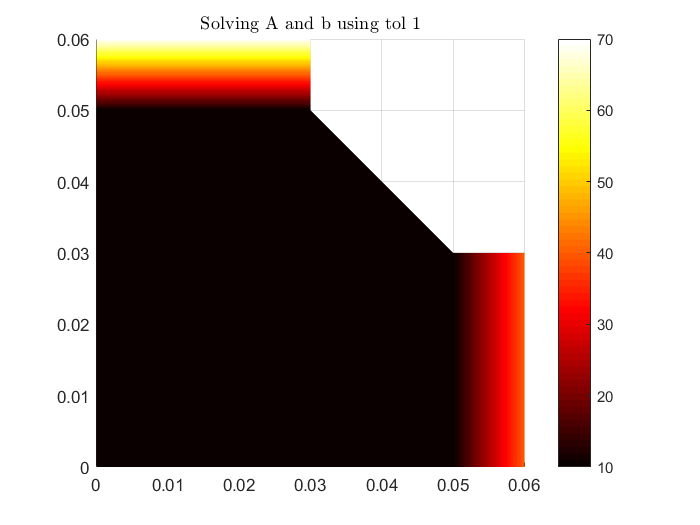

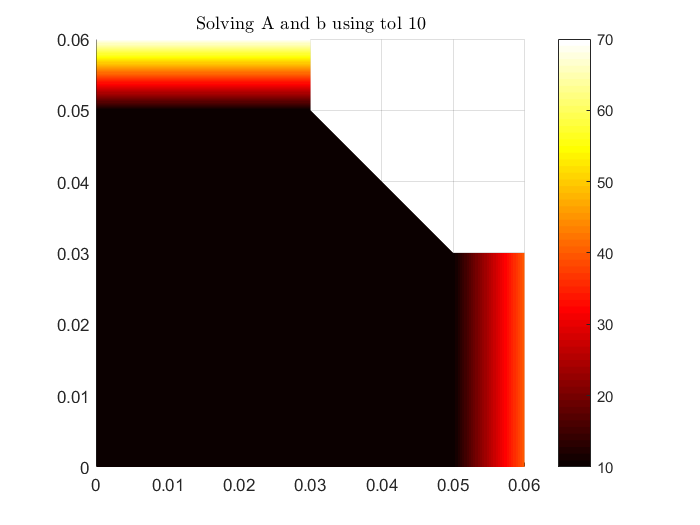

tolVec = [1e-100, 1e-50, 1e-10, 1e-5, 1e-1, 0.5, 1, 10];
[~,n] = size(tolVec);

for i = 1:n
    [temperatures, ~, ~, ~] = sor_CSR(rb, c', v', b, x0, w_opt, tolVec(i), maxiters);
    graphTitle = ['Solving A and b using tol ', num2str(tolVec(i)), ''];
    visualisation(temperatures, graphTitle)
end

Effect of w on the rate of convergence of the SOR method.

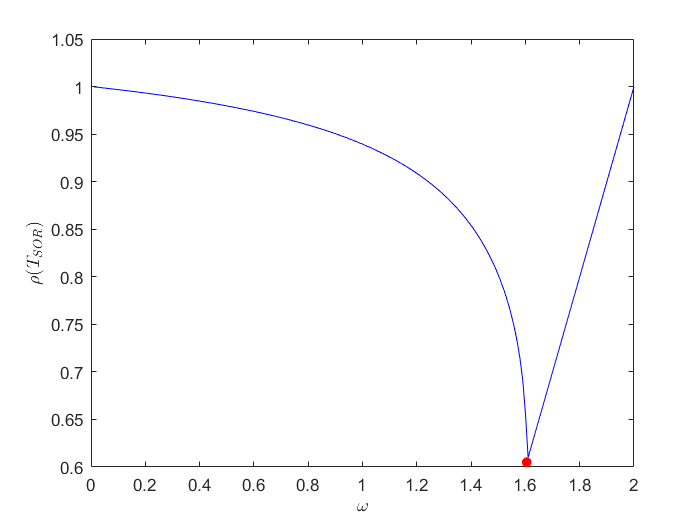

D = diag(diag(A));
L = tril(A, -1);
U = triu(A, 1);
T_J = - (D \ (L + U));
rhoT_J = max(abs(eig(T_J)));
w_opt = (2 /(1 + sqrt(1 - rhoT_J^2)));
T_SOR_opt = (D/w_opt + L) \ ((1-w_opt)/w_opt * D - U);
rhoT_SOR_opt = max(abs(eig(T_SOR_opt)));

wVec = linspace(1e-2,2,200);
rhoT_SOR = zeros(1,200);

for i = 1:200
    w = wVec(i);
    T_SOR = (D/w + L) \ ((1-w)/w * D - U);
    rhoT_SOR(i) = max(abs(eig(T_SOR)));
end

figure;
plot(wVec, rhoT_SOR, 'b')
hold on
plot(w_opt, rhoT_SOR_opt,'r.','Markersize',20);
ylabel('$\rho(T_{SOR})$', 'Interpreter','latex')
xlabel('$\omega$', 'Interpreter','latex')

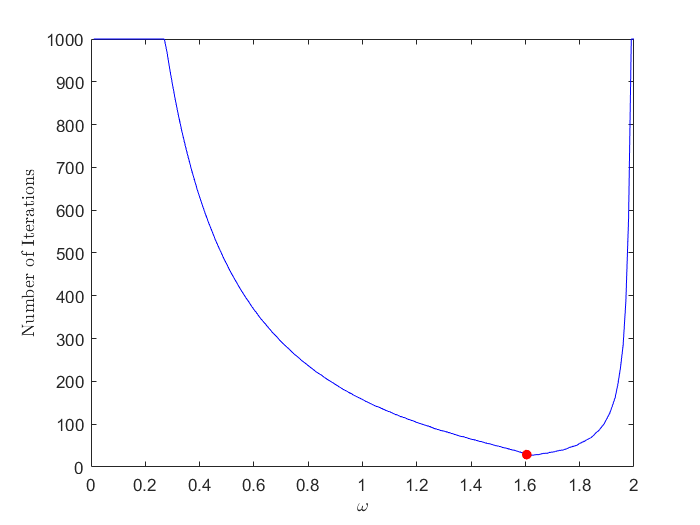


kVec = zeros(1,200);
[~, ~, k_opt, ~] = sor_CSR(rb, c', v', b, x0, w_opt, tol, maxiters);

for i = 1:200
    [~, ~, kVec(i), ~] = sor_CSR(rb, c', v', b, x0, wVec(i), tol, maxiters);
end

figure;
plot(wVec, kVec, 'b')
hold on
plot(w_opt, k_opt,'r.','Markersize',20);
ylabel('Number of Iterations', 'Interpreter','latex')
xlabel('$\omega$', 'Interpreter','latex')